# Homework Assignment 6 : การวิเคราะห์เชิงความถี่

## Objective : 

การบ้านนี้ถูกออกแบบมาเพื่อให้ผู้เรียนได้ประยุกต์การวิเคราะห์เชิงความถี่เพื่อออกแบบตัวกรองความถี่

## หมายเหตุ

ไฟล์สำหรับการส่งการบ้านให้ตั้งชื่อให้อยู่ในรูปแบบดังต่อไปนี้

FRA231_HWลำดับ_รุ่น-รหัสนักศึกษา_รุ่น-รหัสนักศึกษา.zip

ตัวอย่างเช่น: 

นักศึกษารุ่น 6 รหัส 63340200003 ทำงานคู่กับนักศึกษารุ่น 7 รหัส 64340200023

ให้ตั้งชื่อไฟล์ดังนี้ FRA231_HW2_6-3_7-23.zip

ระบบทางกลประกอบด้วยมวลและสปริงที่มีการเคลื่อนที่แบบ Simple Harmonic Motion โดยไม่มีการศสูญเสียพลังงานดังรูปที่ 1 

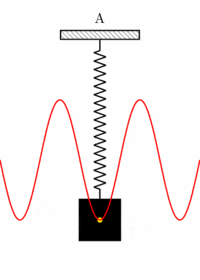

รูปที่ 1 การเคลื่อนที่แบบ Simple Harmonic

การเคลื่อนที่นี้มีขนาด amplitude มีค่าเท่ากับ 1 เมตรและความถี่มีค่าเท่ากับ 5 Hz เมื่อนำ absolute displacement sensor มาติดตั้งกับระบบทางกลพบว่าสามารถอ่านได้จาก sensor มีหน่วยเป็นเมตรดังกราฟ

%load('data.mat')
%plot(ts)

1. จงออกแบบวงจร RC Filter อย่างง่ายเพื่อใช้ในการกรองสัญญาณรบกวนออกจากระบบ โดยนักศึกษาจะต้องเขียนสมการ Transfer Function ของ RC Filter ในไฟล์ Simulink HW6.slx พร้อมอธิบายเหตุผลในการเลือกใช้ค่า R และ C โดยละเอียด

หมายเหตุ : 

- สัญญาณหลังการใช้งาน RC Filter จะต้องมีลักษณะคล้าย Sine Wave ที่มีความถี่ 5 Hz

- ค่า R,C ในการออกแบบต้องใช้ค่ามาตราฐาน E24 เท่านั้น

R = 0.53;
C = 0.06;

(แสดงวิธีทำ)

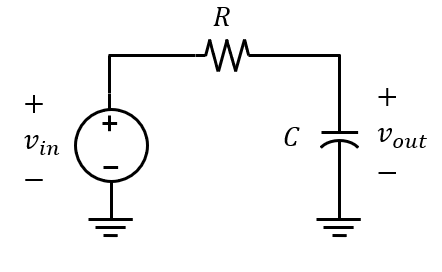

จากวงจร RC Filter เบื้องต้นเราจะสามารถเขียนสมการได้ดังต่อไปนี้


$$v_{\textrm{in}} =\textrm{RC}\frac{{\textrm{dv}}_{\textrm{out}} }{\textrm{dt}}+v_{\textrm{out}}$$


ทำการวิเคราะห์โดยใช้การแปลงลาปซเพื่อจัดรูปให้อยู่ในสมมการ Transfer function


$$\begin{array}{l}
\mathit{\mathbf{L}}\left\lbrace v_{\textrm{in}} \right\rbrace =\mathit{\mathbf{L}}\left\lbrace \textrm{RC}\frac{{\textrm{dv}}_{\textrm{out}} }{\textrm{dt}}+v_{\textrm{out}} \right\rbrace \\
V_{\textrm{in}} \left(s\right)=\textrm{RCs}V_{\textrm{out}} \left(s\right)+V_{\textrm{out}} \left(s\right)\\
\\
\textrm{จะทำให้เราได้}\;\textrm{Transfer}\;\textrm{function}\;\textrm{ดังนี้}\\
G\left(s\right)=\frac{V_{\textrm{out}} \left(s\right)}{V_{\textrm{in}} \left(s\right)}\;=\frac{1}{\textrm{RCs}+1}=\frac{\frac{1}{\textrm{RC}}}{s+\frac{1}{\textrm{RC}}}
\end{array}$$


จาก input ของระบบ Simple Harmonic Motion ที่เข้ามาเป็นรูปแบบของ sine wave เราจึงกำหนดอินพุดอยู่ในรูปดังต่อไปนี้


$$\begin{array}{l}
v_{\textrm{in}} \left(t\right)=R_{\textrm{in}} \cos \left(\omega t+\phi_{\textrm{in}} \right)\\
v_{\textrm{in}} \left(t\right)=R_{\textrm{in}} \cos \left(\phi_{\textrm{in}} \right)\cos \left(\omega t\right)-R_{\textrm{in}} \sin \left(\phi_{\textrm{in}} \right)\sin \left(\omega t\right)\\
\\
\textrm{ทำการแปลง}\;\textrm{input}\;\textrm{ให้อยู่ในโดเมนลาปาซ}\\
V_{\textrm{in}} \left(s\right)=R_{\textrm{in}} \left(\frac{\cos \left(\phi_{\textrm{in}} \right)s-\sin \left(\phi_{\textrm{in}} \right)\omega }{s^2 +\omega^2 }\right)
\end{array}$$


จากสมการ $G\left(s\right)=\frac{V_{\textrm{out}} \left(s\right)}{V_{\textrm{in}} \left(s\right)}\;=\frac{1}{\textrm{RCs}+1}$ =$\frac{\frac{1}{\textrm{RC}}}{s+\frac{1}{\textrm{RC}}}$

เราจะกำหนดให้ $\omega_c =\frac{1}{\textrm{RC}}$ เพื่อให้ง่ายต่อการคำนวณ จะได้ว่า


$$G\left(s\right)=\frac{V_{\textrm{out}} \left(s\right)}{V_{\textrm{in}} \left(s\right)}=\frac{\omega_c }{s+\omega_c }$$


ทำการแทนค่า $V_{\textrm{in}} \left(s\right)$ ลงในสมการ G(s) และ Inverse Laplace จะได้ว่า 


$$V_{\textrm{out}} \left(s\right)=\left(\frac{\omega_c }{s+\omega_c }\right)R_{\textrm{in}} \left(\frac{\cos \left(\phi_{\textrm{in}} \right)s-\sin \left(\phi_{\textrm{in}} \right)\omega }{s^2 +\omega^2 }\right)$$



$$v_{\textrm{out}} \left(t\right)=-\frac{R_{\textrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\left\lbrack \omega \sin \left(\phi_{\textrm{in}} \right)+\omega_c \cos \left(\phi_{\textrm{in}} \right)\right\rbrack e^{-\omega_c t} +R_{\textrm{out}} \cos \left(\omega t+\phi_{\textrm{out}} \right)$$


**เมื่อเวลาผ่านไปพจแรกของ **$v_{\textrm{out}} \left(t\right)$** จะเท่ากับ 0 เนื่องจาก**


$$\lim_{t\to \infty } \left\lbrace v_t \left(t\right)\right\rbrace =-\frac{R_{\textrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\left\lbrack \omega \sin \left(\phi_{\textrm{in}} \right)+\omega_c \cos \left(\phi_{\textrm{in}} \right)\right\rbrack \lim_{t\to \infty } \left\lbrace e^{-\omega_c t} \right\rbrace =0$$


เราจะได้ว่า $v_{\textrm{out}} \left(t\right)=R_{\textrm{out}} \cos \left(\omega t+\phi_{\textrm{out}} \right)$ 


$$R_{\textrm{out}} =\frac{1}{\sqrt{1+{\left(\frac{\omega }{\omega_c }\right)}^2 }}R_{\textrm{in}}$$


วิเคราะห์อัตราส่วนของ $\frac{R_{\textrm{out}} }{R_{\textrm{in}} }$ ในหน่วยเดซิเบล โดยกำหนดให้ $\omega^* =\frac{\omega }{\omega_c }$ จะได้เป็นสมการดังนี้


$${\left|G\left(\omega^* \right)\right|}_{\textrm{dB}} =-10\;\log_{10} \left(1+{\left(\omega^* \right)}^2 \right)$$


เราสามารถวิเคราะห์ย่านของสัญญาณที่ให้ผ่านได้ด้วยสมการ ${\left|G\left(\omega \right)\right|}^2 >\frac{1}{2}{\left|G\left(0\right)\right|}^2$

จะได้ช่วง: $-1<\omega^* <1$ และเนื่องจาก $\omega^*$ เป็นบวกเสมอทำให้เราจะได้ว่าช่วงที่เริ่มมีการเปลี่ยนแปลงของสัญญาณหรือความถี่ตัดนั้นคือ

 
$$\begin{array}{l}
\omega^* =1\\
\frac{\omega }{\omega_c }=1\\
2\pi f\;\textrm{RC}=1\\
\\
\textrm{ความถี่ของ}\;\textrm{input}\;\textrm{คือ}\;5\textrm{Hz}\;\\
10\pi \;\textrm{RC}=1\\
\textrm{RC}=\frac{1}{10\pi \;}\approx 0\ldotp 0318
\end{array}$$


โดยจะเลือกใช้ค่าตามมาตรฐาน E24

ค่า R ใช้ 0.51 ต่ออนุกรมกับ 0.02 จะได้ R = 0.53

ค่า C ใช้ 0.12 อนุกรมกับ 0.12 จะได้ C = 0.06

2. จงหาขนาด Magnitude และ Phase Shift ของ RC Filter ด้วยวิธีการ Bode Plot

(https://www.mathworks.com/help/ident/ref/lti.bode.html)

sys1=tf((1),[1/(10*pi) 1]);

สร้าง transfer function $G\left(S\right)=\frac{1}{\textrm{RCs}+1}$ โดยที่ $\mathrm{RC}=\frac{1}{10\pi \;}$

w=logspace(-1,3);
[mag,phase]=bode(sys1,w);
[magnitudeintersect,phaseintersect] = bode(sys1,10*pi) %เป็นการหาค่าที่จุดดัดที่จุด 10pi ซึ่งเป็นค่าfrequency ของ input

magnitudeintersect =    0.707106781186548


phaseintersect =    -45


เราจะได้ Magnitude คือ 0.7071 และ Phase shift -45 

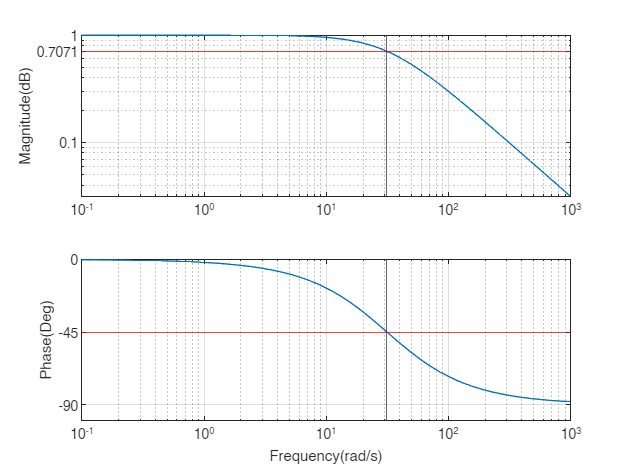

figure
hold on

%กราฟแสดง Magnitude
subplot(2,1,1)
loglog(w,mag(:))
yline(0.7071,'r');
yticks([0.1 0.7071 1]); 
xline(10*pi);
ylabel('Magnitude(dB)')
grid on

%กราฟแสดง Phase Shift
subplot(2,1,2)
semilogx(w,phase(:))
xline(10*pi);
yline(-45,'r');
yticks([-90 -45 0]); 
grid on
ylabel('Phase(Deg)')
xlabel('Frequency(rad/s)')

3. ค่า output ที่ได้หลังจากผ่าน RC Filter มีลักษณะเป็นอย่างไร 

(จงอธิบายอย่างละเอียด)

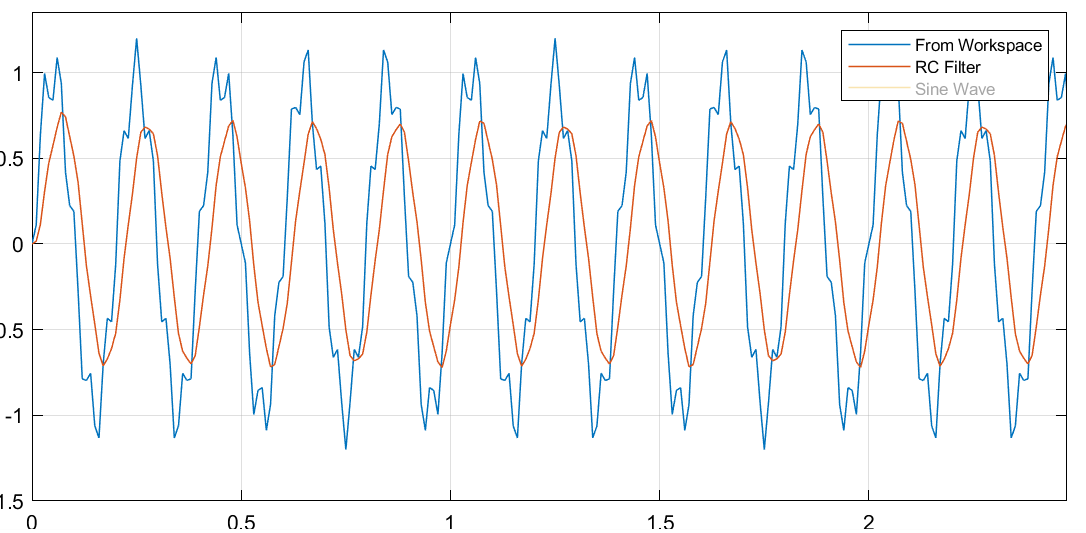

สัญญาณ Output ที่ได้มามี Amplitude ของสัญญาณที่ลดลงจากเดิมที่เข้ามา Amplitude 1 เมื่อผ่านตัว RC Filter แล้วสัญญาณที่ได้จะมี Amplitude อยู่ที่ประมาณ 0.7 ซึ่งตรงกับที่ได้คำนวณออกมาแต่จะเห็นได้ว่าสัญญาณที่ผ่านตัว RC Filter มาจะถูกเลื่อนออกไป -45 องศาจากสัญญาณ Input ตามที่ได้มีการคำนวณข้างต้น

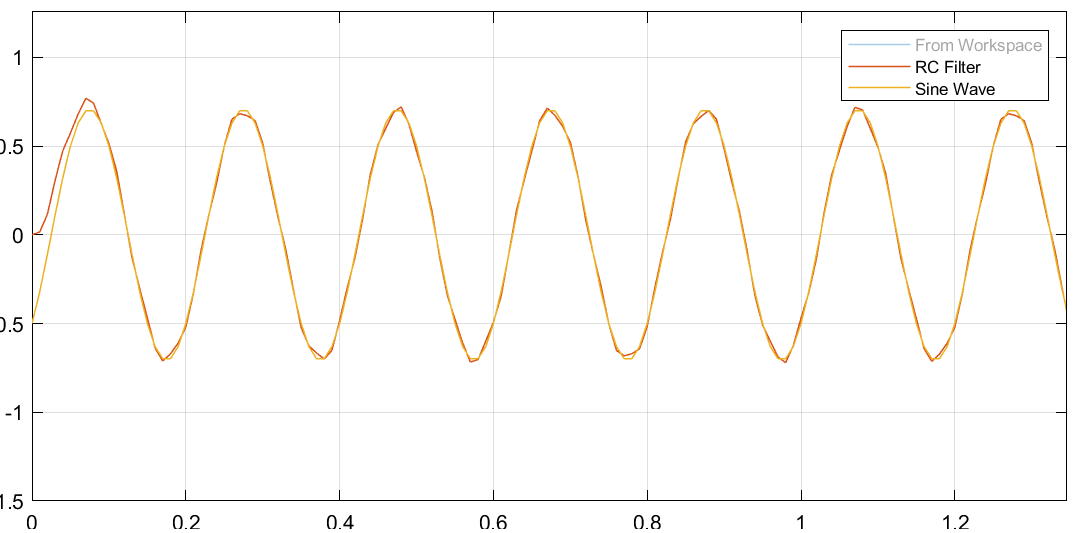

เมื่อเอา Ouput ที่ได้หลังจากผ่าน RC Filter มาเปรียบเทียบกับ Sin Wave โดยตั้ง Parameter ให้สัญญาณมีความถี่ 5[Hz] หรือ $10\pi \;$[Hz] และมุม Phase -45 [degrees] หรือ $\frac{\pi }{4}$ [rad/s] และ Amplitude เท่ากับ 0.7071 จะได้สัญญาณดังรูป ซึ่งจะพบว่า Output ที่ได้หลังจากผ่าน RC Filter มีลักษณะคล้ายกับ Sin wave ความถี่ 5 [HZ] มี Amplitude และ Phase เท่ากับได้มาจากการคำนวณและการทำ Bode plot